# Creation des cartes de visualisation

clear; clc; tic

## Definition des variables contextuelles

pc = 'C:/Users/lehuen201/'; % 'F:/lehuen201/' si travail sur MAGNUM
tsk = 'A_SDM_NEO/';
wdpath = [pc 'Nextcloud/Melting Pot/BDD/']; wdwork = [wdpath,tsk,'Matrices/'];
wdres = [wdpath,tsk,'Resultats/'];
wdgraph = [wdpath,tsk,'Graphiques/'];
pc_sauv = pc; wdpath_sauv = wdpath; wdwork_sauv = wdwork;  wdres_sauv = wdres; wdgraph_sauv = wdgraph; 

test = 2; % 12 Choix si sortie des .shp des data Mars (1) ou des SDM-NEO (2) ou les deux
site = 'ES'; % 'ES' 'BDS' % % geog={'ES','Seine Estuary';'BDS','Bays of Seine';'BDV','Bay of Veys'};
program = {'CSLN','ES';'Mabes','ES';'Fauna','BDS';'Geco','BDV';'Beaug','BDV'};
prog = 1%1:size(program,1);
pr=1 %for pr = prog
prgm = program{pr,1};
% site = program{pr,2};
etudenc = [site,'_Mars'];
etude = [prgm,'_Mars'];

MEVE = [{'MHVE'},{'Maree Haute Vives Eaux'},{'m'}; ...
  {'MHME'},{'Maree Haute Mortes Eaux'},{'m'}; ...
  {'MBME'},{'Maree Basse Mortes Eaux'},{'m'}; ...
  {'MBVE'},{'Maree Basse Vives Eaux'},{'m'}];

nc2d = load ([wdwork, etudenc, '_Nc2D']); % Genere dans Exploitation_Netcdf
bdd = load ([wdwork, prgm, '_BDD']);
nc2d_rq = load ([wdwork, etude, '_Nc2D_RQ']);
spe = 1%:nrow(species); % 1:CERED 2:CORVO 3:HEDDI 4:LIMBA 5:PERUL 6:SCRPL
answ = 1% :nrow(reponse) % 1:Itot 2:MSR 3:Density_indm2 4:Biomass_gAFDWm2
sai = 1:size(nc2d.saison,1);
sitetxt = bdd.geog{strcmp(bdd.geog(:,1),site),2}; % METTRE DANS LES TITRES DES GRAPHES LE SITE

#### Definition des donnees relatives au site

% an = [1990:2000 2005:2018];
an = [2018]; % Pour la BDS que 2018 de sorti
leapyear=@(yr)~rem(yr,400)|rem(yr,100)&~rem(yr,4);

% if strcmp(site,'ES')
%     boxcenter = [0.13, 49.49];
%     box_lon = [-0.01, 0.39]; 
%     box_lat = [49.35, 49.55];
% elseif strcmp(site,'BDS')
%     boxcenter = [0.13, 49.49];
%     box_lon = [-1.2, 0.39]; 
%     box_lat = [49.35, 49.55];
% elseif strcmp(site,'BDV')
%     boxcenter = [-1.14, 49.38];
%     box_lon = [-1.2, -1]; 
%     box_lat = [49.35, 49.40];
% end


#### Definition des bornes spatiales d'intéret

% boxfrmetro = [-4.87, 42.33; 8.23, 51.14]; % Selon LambII EPSG 27572 % xfrmetro=[-9.86,10.38]; yfrmetro=[41.15,51.56] % Coord selon L93 EPSG 2154
% boxnormx = [-2, 0.8]; boxnormy = [49, 50];
% boxbdsx = [-0.1, 0.45]; boxbdsy = [49.3, 49.7];
% boxestx = [0.1, 0.2]; boxesty = [49.35, 49.55];

#### Definition des donnees relatives au programme

% eval(['bdd.dm_bdd = bdd.' prgm '_Mars' ';']);
% eval(['bdd.species = bdd.species_' prgm ';']);
% eval(['bdd.reponse = bdd.reponse_' prgm ';']);
% eval(['bdd.predict = bdd.predict_' prgm ';']);

finesse = 100;
csp = 4; lsp = ceil(size(an,2)/csp);
propplch = [0 0 csp*150+100 lsp*150];  propimg = [0 0 csp*150+100 lsp*150];

# Creation csv experiment plan

% writetable(bdd.sampleplan,[wdres,prgm,'_XpPlan','.csv']);

## Lancement de la boucle annuelle

% ann = 1;
for ann = 1:length(an)
    anstr = num2str(an(ann))

# Donnees MARS3D

### Construction du csv des résultats

if test==1 || test==12
% %     try
%     lon = eval(['nc2d.lon_nc_' anstr ';']);
%     lat = eval(['nc2d.lat_nc_' anstr ';']);
%     NINJ = eval(['nc2d.NINJ_' anstr ';']);
%     Mars_Maps=array2table([lon(:) lat(:)],'VariableNames',{'Lon','Lat'});
%     Mars_Maps=[Mars_Maps table(convertStringsToChars(NINJ(:)),'VariableNames',{'NINJ'})];
% %     Mars_Maps.Zone=cell(size(Mars_Maps,1),1);
% %     filename =[pc 'Nextcloud\Melting Pot\SIG\Couches créées\Masque_Zone_ES_WGS.shp'];
%     filename =[pc 'Nextcloud\Melting Pot\SIG\Maillage Mars3D\Maillage_mars3D_WGS.shp'];
% %     Masque_Zone = shaperead(filename, 'UseGeoCoords', true);
% %     for k=1:size(Masque_Zone,1)
% %         if ~strcmp(Masque_Zone(k).Zone,'NaN') %
% %             in = find(inpolygon(Mars_Maps.Lat,Mars_Maps.Lon, Masque_Zone(k).Lat',Masque_Zone(k).Lon'));
% %             Mars_Maps.Zone(in) = {Masque_Zone(k).Zone};
% %         end
% %     end
%     predict_hyd=nc2d.predict_hyd;
%     for i=1:length(predict_hyd)
%         eval(['tmp = table(nc2d.' predict_hyd{i,1} '_' anstr '(:),''VariableNames'',{''' predict_hyd{i,1}  '''});'])
%         eval(['tmps = table(nc2d.' predict_hyd{i,1} '_s_' anstr '(:),''VariableNames'',{''' predict_hyd{i,1}  '_s''});'])
%         eval(['tmpw = table(nc2d.' predict_hyd{i,1} '_w_' anstr '(:),''VariableNames'',{''' predict_hyd{i,1}  '_w''});'])
%         Mars_Maps=[Mars_Maps tmp tmps tmpw];
%     end
%     predict_sed=nc2d.predict_sed;
%     for i=1:length(predict_sed)
%         eval(['tmp = table(nc2d.' predict_sed{i,1} '_' anstr '(:),''VariableNames'',{''' predict_sed{i,1}  '''});'])
%         eval(['tmps = table(nc2d.' predict_sed{i,1} '_s_' anstr '(:),''VariableNames'',{''' predict_sed{i,1}  '_s''});'])
%         eval(['tmpw = table(nc2d.' predict_sed{i,1} '_w_' anstr '(:),''VariableNames'',{''' predict_sed{i,1}  '_w''});'])
%         Mars_Maps=[Mars_Maps tmp tmps tmpw];
%     end
%     MEVE=nc2d.MEVE;
%     for i=1:length(MEVE)
%         eval(['tmp = table(nc2d.' MEVE{i,1} '_' anstr '(:),''VariableNames'',{''' MEVE{i,1}  '''});'])
%         Mars_Maps=[Mars_Maps tmp];
%     end
%     
%     listvar = Mars_Maps.Properties.VariableNames(:,5:end);
%     for va = 1:size(listvar,2)
%         eval(['Mars_Maps.' listvar{va} '= double(Mars_Maps.' listvar{va} ');']);
%     end
%     eval(['Mars_Maps_' anstr '= Mars_Maps;']);
% %     Mars_Maps_sh=Mars_Maps(~cellfun(@isempty, Mars_Maps.Zone), :);    
%     Mars_Maps_sh=Mars_Maps;    
% %     Mars_Maps_sh(isnan(Mars_Maps_sh.Lat),:)=[];
%     eval(['Mars_Maps_sh_' anstr '= Mars_Maps_sh;']);
%     
% %     writetable(Mars_Maps_sh,[wdres,'Mars_Maps_',anstr,'.csv']);

#### Ajout Zone Estuaire et var Mars dans Maillage Mars3D.shp

%     filename =[pc 'Nextcloud\Melting Pot\SIG\Maillage Mars3D\Maillage_mars3D_WGS.shp'];
%     Maille_nc = shaperead(filename,'UseGeoCoords',true);
%     maille_t=struct2table(Maille_nc);
%     [~,maille_i]=setdiff(maille_t.id_maille,Mars_Maps_sh.NINJ);
%     Maille_nc([maille_i])=[];
%     maille_t=struct2table(Maille_nc);
%     [~, idx] = ismember(maille_t.id_maille,Mars_Maps_sh.NINJ);
%     [Maille_nc.NINJ_v] = Mars_Maps_sh.NINJ{idx};
%     tmp=num2cell(Mars_Maps_sh.Lat(idx)); [Maille_nc.Lon_c] = tmp{:};
%     tmp=num2cell(Mars_Maps_sh.Lon(idx)); [Maille_nc.Lat_c] = tmp{:};
% %     [Maille_nc.Zone] = Mars_Maps_sh.Zone{idx};
%      
%     for va = 1:size(listvar,2)
%         eval(['tmp=num2cell(Mars_Maps_sh.' listvar{va} '(idx));']);
%         eval(['[Maille_nc.' listvar{va} '] = tmp{:};']);
%     end
%     eval(['Maille_nc_' anstr '= Maille_nc;']);
%     shapewrite(Maille_nc,[wdres,'Shapefile/',site,'_Maille_nc_',anstr,'.shp']);

% %     catch e
% %         fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
% %     end % try à partir de mars

# Resultats SDM-NEO

### Construction du csv des résultats

elseif test == 2 || test==12
%     try
    lon = eval(['nc2d.lon_nc_' anstr ';']);
    lat = eval(['nc2d.lat_nc_' anstr ';']);
    NINJ = eval(['nc2d.NINJ_' anstr ';']);
    Mars_rq_Maps=array2table([lon(:) lat(:)],'VariableNames',{'Lon','Lat'});
    Mars_rq_Maps=[Mars_rq_Maps table(convertStringsToChars(NINJ(:)),'VariableNames',{'NINJ'})];
    
    filename =[pc 'Nextcloud\Melting Pot\SIG\Couches créées\Masque_Zone_ES_WGS.shp'];
    Masque_Zone = shaperead(filename, 'UseGeoCoords', true);
    for k=1:size(Masque_Zone,1)
        if ~strcmp(Masque_Zone(k).Zone,'NaN') %
            in = find(inpolygon(Mars_rq_Maps.Lat,Mars_rq_Maps.Lon, Masque_Zone(k).Lat',Masque_Zone(k).Lon'));
            Mars_rq_Maps.Zone(in) = {Masque_Zone(k).Zone};
        end
    end
    sdm=nc2d_rq.sdm;
    for i=1:4%size(sdm,1)
        eval(['tmp = table(nc2d_rq.' sdm{i,1} '_' anstr '(:),''VariableNames'',{''' sdm{i,1}  '''});'])
        eval(['tmps = table(nc2d_rq.' sdm{i,1} '_s_' anstr '(:),''VariableNames'',{''' sdm{i,1}  '_s''});'])
        eval(['tmpw = table(nc2d_rq.' sdm{i,1} '_w_' anstr '(:),''VariableNames'',{''' sdm{i,1}  '_w''});'])
        Mars_rq_Maps=[Mars_rq_Maps tmp tmps tmpw];
    end
    listvar = Mars_rq_Maps.Properties.VariableNames(:,5:end);
    for va = 1:size(listvar,2)
        eval(['Mars_rq_Maps.' listvar{va} '= double(Mars_rq_Maps.' listvar{va} ');']);
    end
    eval(['Mars_rq_Maps_' anstr '= Mars_rq_Maps;']);
    Mars_rq_Maps_sh=Mars_rq_Maps(~cellfun(@isempty, Mars_rq_Maps.Zone), :);    
%     Mars_rq_Maps_sh(isnan(Mars_rq_Maps_sh.Lat),:)=[];
    eval(['Mars_rq_Maps_sh_' anstr '= Mars_rq_Maps_sh;']);
    
%     writetable(Mars_rq_Maps_sh,[wdres,'Mars_rq_Maps_',anstr,'.csv']);

#### Ajout Zone Estuaire et var Mars dans Maillage Mars3D.shp

    filename =[pc 'Nextcloud\Melting Pot\SIG\Maillage Mars3D\Maillage_mars3D_WGS.shp'];
    Maille_rq = shaperead(filename,'UseGeoCoords',true);
    maille_t=struct2table(Maille_rq);
    [~,maille_i]=setdiff(maille_t.id_maille,Mars_rq_Maps_sh.NINJ);
    Maille_rq([maille_i])=[];maille_t=struct2table(Maille_rq);
    [~, idx] = ismember(maille_t.id_maille,Mars_rq_Maps_sh.NINJ);
    [Maille_rq.NINJ_v] = Mars_rq_Maps_sh.NINJ{idx};
    tmp=num2cell(Mars_rq_Maps_sh.Lat(idx)); [Maille_rq.Lon_c] = tmp{:};
    tmp=num2cell(Mars_rq_Maps_sh.Lon(idx)); [Maille_rq.Lat_c] = tmp{:};
    [Maille_rq.Zone] = Mars_rq_Maps_sh.Zone{idx};
     
    for va = 1:size(listvar,2)
        eval(['tmp=num2cell(Mars_rq_Maps_sh.' listvar{va} '(idx));']);
        eval(['[Maille_rq.' listvar{va} '] = tmp{:};']);
    end
    eval(['Maille_rq_' anstr '= Maille_rq;']);
    shapewrite(Maille_rq,[wdres,'Shapefile/',site,'_Maille_rq_',anstr,'.shp']);

%     catch e
%         fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
%     end % try à partir de SDM
end

## Save workspace

    if test == 1 || test == 12
    if exist([wdwork, etude, '_Map.mat'])==0; save ([wdwork, etude, '_Map'],'ann'); end
    try save ([wdwork, etude, '_Map'], ['Mars_Maps_' anstr], ['Mars_Maps_sh_' anstr], ['Maille_nc_' anstr], '-append')
    catch e
        fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
    end
    elseif test == 2 || test == 12
    if exist([wdwork, 'SDM-NEO', '_Map.mat'])==0; save ([wdwork, 'SDM-NEO', '_Map'],'ann'); end
    try save ([wdwork, 'SDM-NEO', '_Map'], ['Mars_rq_Maps_' anstr], ['Mars_rq_Maps_sh_' anstr], ['Maille_rq_' anstr], '-append')
    catch e
        fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
    end
    end
    % save ([wdwork, etude, '_Carto','_BDD']);

## Fin de la boucle

end % boucle an
% beep
toc
load gong.mat; sound(y);

## Visualisation Reponses par an

### Planche de tous les ans

% %% Choix de l'espece: 1:CERED 2:CORVO 3:HEDDI 4:LIMBA 5:PERUL 6:SCRPL
% for idx = 1:length(SpCh)
% dm_map = dm_bdd(dm_bdd.SPCourt == SpCh(idx),:);
% dm_map.Zone = categorical(dm_map.Zone);
%     boxx = [min(dm_bdd.longitude), max(dm_bdd.longitude)]; 
%     boxy = [min(dm_bdd.latitude), max(dm_bdd.latitude)];
% %% Choix de la reponse : 1:Density 2:Biomass
%     figure;clf; hold on
%     for rep = 1 % :size(reponse,1)
%     maxx=eval(strcat("max(dm_map.", reponse{rep,1},")")); minn=eval(strcat("min(dm_map.", reponse{rep,1},")")); 
%     rgvar = [minn maxx];
%     set(gcf, 'Position', propplch);
%         for ye = 1:length(an)
%             anstr=num2str(an(ye));
%             dm_map_an = dm_map(dm_map.Annee == anstr,:);
%             subplot(lsp,csp,ye);
%             geobubble(dm_map_an,'latitude','longitude','SizeVariable',reponse{rep,1},'ColorVariable','Zone',...
%                 'BubbleWidthRange', [4 15], 'SizeLimits', rgvar,...
%                 'SizeLegendTitle',reponse{rep,2},'Basemap','satellite','MapCenter',boxcenter); % topographic satellite streets-light
%             geolimits(boxy,boxx)
%             title(anstr);
%         end
%     titreG = sprintf('%s of %s per year',reponse{rep,2},string(SpCh(idx)));
%     [~,h3] = suplabel(titreG ,'t'); set(h3,'FontSize',9);
%     hold off
%     saveas(gcf,strcat(wdgraph,string(SpCh(idx)),'/',etude,'_Map_',string(SpCh(idx)),'_',reponse{rep,1},'.png'));
%     end
% end

### Une figure par an

% %% Choix de l'espece: 1:CERED 2:CORVO 3:HEDDI 4:LIMBA 5:PERUL 6:SCRPL
% for idx = 1%:length(SpCh)
% dm_map = dm_bdd(dm_bdd.SPCourt == SpCh(idx),:);
% dm_map.Zone = categorical(dm_map.Zone);
%     boxx = [min(dm_bdd.longitude), max(dm_bdd.longitude)]; 
%     boxy = [min(dm_bdd.latitude), max(dm_bdd.latitude)];
%     for rep = 1 % :size(reponse,1)
%     maxx=eval(strcat("max(dm_map.", reponse{rep,1},")")); minn=eval(strcat("min(dm_map.", reponse{rep,1},")")); 
%     rgvar = [minn maxx];
%     set(gcf, 'Position', propplch);
%         for ye = 1%:length(an)
%             figure;clf;
%             anstr=num2str(an(ye));
%             dm_map_an = dm_map(dm_map.Annee == anstr,:);
%             geobubble(dm_map_an,'latitude','longitude','SizeVariable',reponse{rep,1},'ColorVariable','Zone',...
%                 'BubbleWidthRange', [4 15], 'SizeLimits', rgvar,...
%                 'SizeLegendTitle',reponse{rep,2},'Basemap','topographic','MapCenter',boxcenter); % topographic satellite streets-light
%             geolimits(boxy,boxx);
%             titreG = sprintf('%s of %s per %s',reponse{rep,2},string(SpCh(idx)),anstr);
%             title(titreG);
%             saveas(gcf,strcat(wdgraph,string(SpCh(idx)),'/',etude,'_Map_',string(SpCh(idx)),'_',reponse{rep,1},'_',anstr,'.png'));
%         end
%     end
% end

## Data d'étude : fond de carte et BDD geolocalisee

% fdc = shaperead(strcat(wdshp,"communes-20150101-5m.shp"),'BoundingBox',boxnorm,'UseGeoCoords', true);
% mapshow(fdc);
% worldmap Europe
% load coastlines
% plotm(coastlat,coastlon)
% lat = fdc.Lat; lon = fdc.Lon;
% geoshow(lat,lon,'DisplayType','polygon')

Surface gaussienne théorique

palette = 'jet';
N = 3.0;
x=linspace(-N, N,80); y=x;

[X,Y]=meshgrid(x,y);
Z=exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
surf(X,Y,Z,'EdgeColor','flat'); %,'LineStyle','none'
% contourf(X,Y,Z,50, 'LineColor','flat'); colorbar;
xlabel('Physical Predictor 1','FontSize',24); ylabel('Physical Predictor 2','FontSize',24); zlabel('Biological Response','FontSize',24);
colormap(palette); camlight; 
axis tight
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])

z=exp(-(x.^2/2))/sqrt(2*pi);
plot(x,z); hold on
N = numel(x);
for ii = ceil(N/2):N-1
       ix = [ii ii+1 N-ii N-ii+1];
%        disp(ix);
       patch(x(ix), z(ix), z(ii)*256/max(z(:)),'edgecolor', 'none');
end
xlabel('Physical Predictor','FontSize',24); ylabel('Biological Response','FontSize',24);
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
hold off

plot(x,z); hold on
verts = [x(:), z(:); x(:) zeros(N,1)];
q = (1:N-1)';
faces = [q, q+1, q+N+1, q+N];
p = patch('Faces', faces, 'Vertices', verts, 'FaceVertexCData', [z(:); z(:)], 'FaceColor', 'interp', 'EdgeColor', 'none');
xlabel('Physical Predictor','FontSize',24); ylabel('Biological Response','FontSize',24);
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
hold off



Illustration de la régression quantile

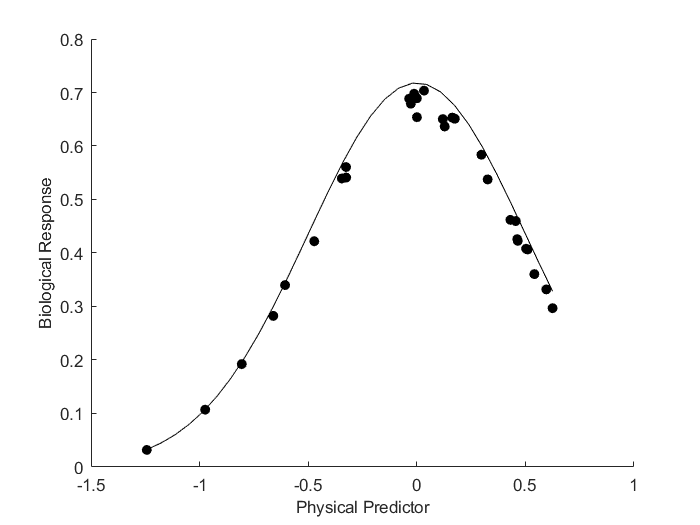

wdillustr = 'C:/Users/lehuen201/Nextcloud/Melting Pot/Rapport - Presentations/Images/';
listcol=[0, 0.4470, 0.7410; %hsv(5);%
         0.8500, 0.3250, 0.0980;
         0.9290, 0.6940, 0.1250;
         0.4940, 0.1840, 0.5560;
         0.4660, 0.6740, 0.1880];%;
%          0.3010, 0.7450, 0.9330;
%          0.6350, 0.0780, 0.1840];
palette = 'jet';
N=30; mu=0; sigma=0.5;
limfact=[.25 .5 .75 .9];
xr=normrnd(mu,sigma,N,1); yr=linspace(.1,.9,N/5)';

z1=limfact(1).*normpdf(xr,mu,sigma).*(8.*rand(N,1))/10;
    zt1 = limfact(1).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z2=limfact(2).*normpdf(xr,mu,sigma).*(4+6.*rand(N,1))/10;
    zt2 = limfact(2).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z3=limfact(3).*normpdf(xr,mu,sigma).*(6+4.*rand(N,1))/10;
    zt3 = limfact(3).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z4=limfact(4).*normpdf(xr,mu,sigma).*(9+rand(N,1))/10;
    zt4 = limfact(4).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z5 = normpdf(xr,mu,sigma);
    zt5 = normpdf(linspace(min(xr),max(xr),N),mu,sigma);

scatter(xr,z4,[],'k','filled') %listcol(1,:)
hold on
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show10.png',wdillustr),'-dpng','-r600');
plot(linspace(min(xr),max(xr),N),zt4,'color','k') %listcol(1,:)
hold off
print(gcf,sprintf('%sQR_show11.png',wdillustr),'-dpng','-r600');

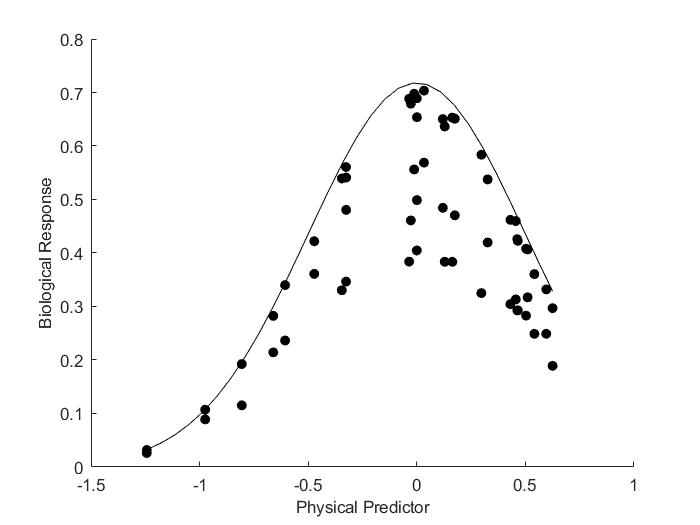


% scatter(xr,z5,[],listcol(1,:),'filled')
scatter(xr,z4,[],'k','filled') %listcol(1,:)
hold on
scatter(xr,z3,[],'k','filled') %listcol(2,:)
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show20.png',wdillustr),'-dpng','-r600');
% plot(linspace(min(xr),max(xr),N),zt5,'color',listcol(1,:))
plot(linspace(min(xr),max(xr),N),zt4,'color','k') %listcol(1,:)
% plot(linspace(min(xr),max(xr),N),zt3,'color',listcol(2,:))
hold off
print(gcf,sprintf('%sQR_show21.png',wdillustr),'-dpng','-r600');

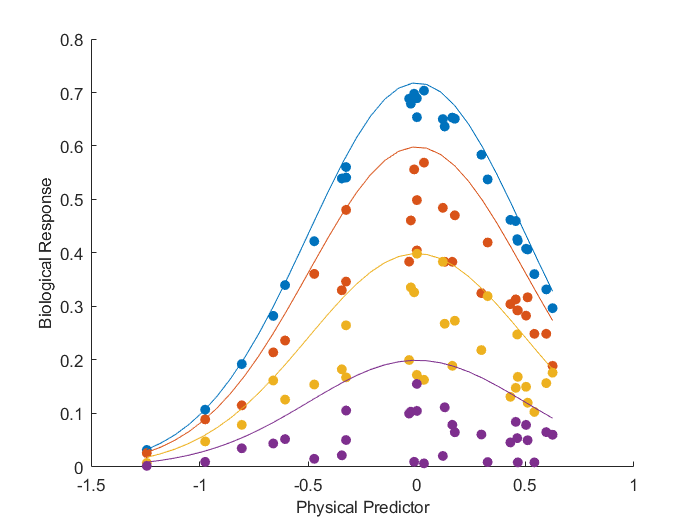


% scatter(xr,z5,[],listcol(1,:),'filled')
scatter(xr,z4,[],'k','filled')
hold on
scatter(xr,z3,[],'k','filled')
scatter(xr,z2,[],'k','filled')
scatter(xr,z1,[],'k','filled')
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show30.png',wdillustr),'-dpng','-r600');
scatter(xr,z4,[],listcol(1,:),'filled')
scatter(xr,z3,[],listcol(2,:),'filled')
scatter(xr,z2,[],listcol(3,:),'filled')
scatter(xr,z1,[],listcol(4,:),'filled')
% plot(linspace(min(xr),max(xr),N),zt5,'color',listcol(1,:))
plot(linspace(min(xr),max(xr),N),zt4,'color',listcol(1,:))
plot(linspace(min(xr),max(xr),N),zt3,'color',listcol(2,:))
plot(linspace(min(xr),max(xr),N),zt2,'color',listcol(3,:))
plot(linspace(min(xr),max(xr),N),zt1,'color',listcol(4,:))
hold off
print(gcf,sprintf('%sQR_show31.png',wdillustr),'-dpng','-r600');

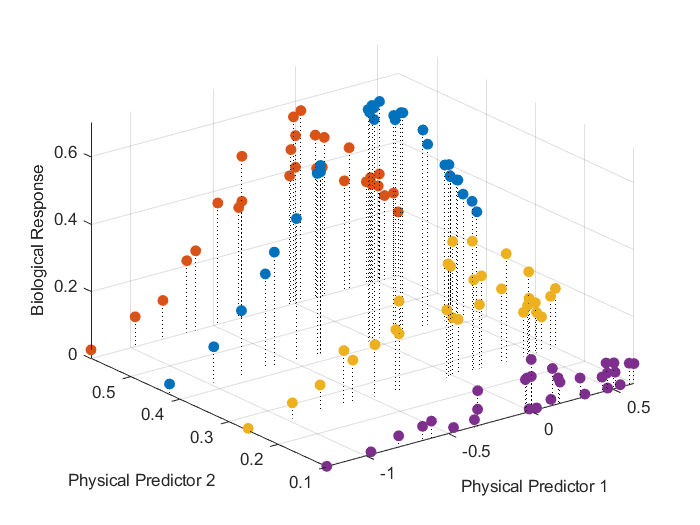


[X,Y]=meshgrid(linspace(min(xr),max(xr),N),linspace(min(yr),max(yr),N/5));

Z1=limfact(1)*exp(-(xr.^2/2)-(yr(1).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt1=limfact(1)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z2=limfact(2)*exp(-(xr.^2/2)-(yr(2).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt2=limfact(2)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z3=limfact(3)*exp(-(xr.^2/2)-(yr(4).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt3=limfact(3)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z4=limfact(4)*exp(-(xr.^2/2)-(yr(3).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt4=limfact(4)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
figure
stem3(xr,repmat(yr(1),N,1),z1,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(4,:),'MarkerEdgeColor',listcol(4,:))
hold on
stem3(xr,repmat(yr(2),N,1),z2,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(3,:),'MarkerEdgeColor',listcol(3,:))
stem3(xr,repmat(yr(4),N,1),z3,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(2,:),'MarkerEdgeColor',listcol(2,:))
stem3(xr,repmat(yr(3),N,1),z4,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(1,:),'MarkerEdgeColor',listcol(1,:))

% surf(X,Y,Zt4,'EdgeColor','flat','LineStyle','none');
% surf(X,Y,Zt3,'EdgeColor','flat'); %,'LineStyle','none'
% surf(X,Y,Zt2,'EdgeColor','flat'); %,'LineStyle','none'
% surf(X,Y,Zt1,'EdgeColor','flat'); %,'LineStyle','none'
hold off
xlabel('Physical Predictor 1','FontSize',10); ylabel('Physical Predictor 2','FontSize',10); zlabel('Biological Response','FontSize',10);
colormap(palette); alpha(.2);
axis tight
% set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
print(gcf,sprintf('%sQR_show40.png',wdillustr),'-dpng','-r600');